## Systems of Differential Equations

In this livescript, you will learn how

- To reduce higher order differential equations to systems of first order differential equations

- To solve the resulting set of equations numerically and using MATLAB.

Consider the motion of a spring-mass system

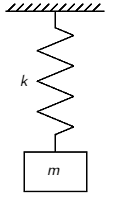

Applying Newton's second law gives the following second order differential equation


$$m\frac{d^{2}x}{dt^{2}}+kx=0$$


*Equation 1.*

where $$x$$ is the position, $$m$$ is the mass, and $$k$$ is the spring constant.

We'll assume that $k=1$ and the mass is initially stationary at $x=1$.

While numerical methods to directly integrate this second order equation do exist, such as the *Runge-Kutta-Nyström* method, the numerical methods that we have covered have been focused on solving first order differential equations of the form


$$ \frac{d}{dt}\{x\}=f(t,\{x\})$$


where $$\{x\}$$ can either be a vector or a scalar variable, and $$t$$ is time.

Therefore, we need a way of converting our higher order equations into first order equations.

The process is quite simple, and boils down into the following steps.

**Step 1. **Define $$N$$ new variables for $$x$$ and its derivatives, where $ $N$$ is the order of the differential equation.

Here Eq. (1) is of order 2, so we define the following variables for $$x$$ and $$dx/dt$$


$$x_{1}=x\\
x_{2}=\frac{dx}{dt}$$


*Equations 2a and 2b.*

**Step 2.** Relate the variables defined in Step 1 by differentiating them.

Differentiating $$x_{1}$$ and applying Eq. (2a) gives


$$\frac{dx_{1}}{dt}=\frac{dx}{dt}=x_{2}$$


*Equation 3.*

Whereas, differentiating $ $x_{2}$$ and using Eq. (2b) and Eq. (1), we find that 


$$\frac{dx_{2}}{dt}=\frac{d}{dt}\Big(\frac{dx}{dt}\Big)=-kx$$


*Equation 4.*

**Step 3.** Use the equations derived in Step 2 to rewrite the differential equation as a system of first order differential equations.

Using Eq. (3) and Eq. (4), Eq. (1) can be written as the following system of first order ordinary differential equations.


$$ \frac{dx_{1}}{dt}=x_{2}\\
        \frac{dx_{2}}{dt}=-kx_{1}$$


Or equivalently as the matrix differential equation


$$\pmatrix{
\frac{dx_{1}}{dt}\cr
\frac{dx_{2}}{dt}
}
=
\pmatrix{
x_{2}\cr
-kx_{1}
}$$


### Solving in MATLAB

With very minor modifications to the what we have done previously, we can use $\texttt{ode45}$ to solve this system of equations. 

Instead of specifying a scalar function handle, we can modify it to output the vector above, which gives the function

$\texttt{tspan}
$ is still the interval $\texttt{tspan = [ti tf]}$. So, to solve the IVP within the interval $0\leq t \leq 10$, we have

tspan = [0 10]

$\texttt{x0}
$ is a now a vector of the initial conditions, which in our case is given by

x0 = [1,0];

With these pieces, we can then call $\texttt{ode45}
$ using the following command

[t,xe] = ode45(@odefun,tspan,x0);

Plotting gives

plot(t,xe)
xlabel('t')
ylabel('x')
xlim([0,10])

Note that the output from $\texttt{ode45}$ consists of a matrix of the form


$$\pmatrix{
\phi_{1}^0 & \phi_{2}^0 \cr
\phi_{1}^1 & \phi_{2}^1 \cr
\phi_{1}^2 & \phi_{2}^2 \cr
\phi_{1}^3 & \phi_{2}^3 \cr
\vdots & \vdots
}$$


where the columns denote the two functions and the rows are the values at each time step.

### Numerical Methods

To illustrate how you would code up something to solve the IVP, we'll use the RK2 method as it's quite simple but is still complex enough for you to see how higher order RK methods may be used.

One thing to note is that although the numerical methods you has seen thus far have only been applied to single first order differential equations, it's easy to generalise them to a system of differential equations by vectorising $f$, $\phi$, $k_{1}$, and $k_{2}$. This essentially boils down to putting curly brackets around each term.

Therefore, the vectorised RK2 method is given by the following difference equations


$$\{\phi\}^{\ell+1}=\{\phi\}^{\ell}+h\Big(\frac{1}{2}\{k_{1}\}+\frac{1}{2}\{k_{2}\}\Big)$$


where 


$$\{k_{1}\}=\{f\}(t^{\ell},\{\phi\}^{\ell})\\
\{k_{2}\}=\{f\}(t^{\ell}+h,\{\phi\}^{\ell}+h\{k_{1}\})$$


(a)        Write out the RK2 method with

$\{x\}
=
\pmatrix{
x_{1} \cr
x_{2}
}$, $\{f\}
=
\pmatrix{
x_{2}\cr
-kx_{1}
}$

The first step in solving an IVP is to set the initial conditions and as always initialise any variables. 

We're going to try and follow the syntax of MATLAB's ODE solvers as close as possible, so this includes a function handle of the system of ODEs to solve $\texttt{odefun}$, $\texttt{tspan}$, and the initial conditions. We've also added $N$ as the number of time steps as $\texttt{ode45}$ is a *variable-step solver*, meaning that it changes the step size depending on the error, which we don't need to worry about.

f = @odefun;
tspan = [0,10];
x0 = [1,0];
N = 100;

This next piece of code initialises the output matrix where each row is a new time-step and each column is the output for each variable.

x = zeros(N+1,2);
x(1,:) = x0;

Since the number of time steps is $N$, then the step size is given as $h=(t_{f}-t_{i})/N$

dt = (tspan(2)-tspan(1))/N;
t1 = linspace(tspan(1),tspan(2),N+1);

As there are a known number of steps taken, a for loop can be used to compute each iterate

for l = 1:N
    k1 = f(t1(l),x(l,:))';
    k2 = f(t1(l+1),x(l,:)+dt*k1)';
    x(l+1,:) = x(l,:)+dt*(0.5*k1+0.5*k2);
end

plot(t1,x,'x-')
hold on
plot(t,xe,'^-')
hold off
legend('Explicit Euler x_{1}','Explicit Euler x_{2}','ode45 x_{1}','ode45 x_{2}','Location','northwest')
xlabel('t')
ylabel('x_{1},x_{2}')

function dxdt = odefun(t,x)
   k = 1;
   dxdt = [x(2);
        -k.*x(1)];
end